# Manual Fourier Transform

## A generalized DFT with non-integral sinusoidal frequencies

Start by generating a known multi-sinusoid signal

The signal definition will be a matrix G:


$$\left\lbrack \begin{array}{ccc}
A_1  & \omega_1  & \phi_1 \\
A_2  & \omega_2  & \phi_2 \\
A_n  & \omega_n  & \phi_n 
\end{array}\right\rbrack$$


##  
$$g(t)=\sum_{n=0}^MA_ncos(\omega_n t + \phi_n)$$


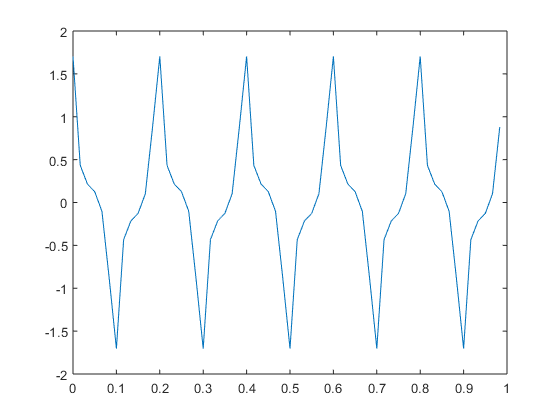

clear all
% signal parameters
G = [1,2*pi*5,0; .5,2*pi*15,pi/8; .25,2*pi*25,pi/12];
%G = [1,2*pi*5.1,0; .5,2*pi*15.3,pi/8; .25,2*pi*25.5,pi/12];
s=(size(G));

%generate signal
N = 60;    %sample size
Fs = 60;    %sample rate
t=(0:1/Fs:(N-1)/Fs);
g=zeros(1,N);
for i= 0:s(1)-1
    for n = 0:N-1
        g(n+1) = g(n+1)+G(i+1,1)*cos(G(i+1,2)*t(n+1)+G(i+1,3));
    end
end
figure
plot(t,g)

# Simple DFT

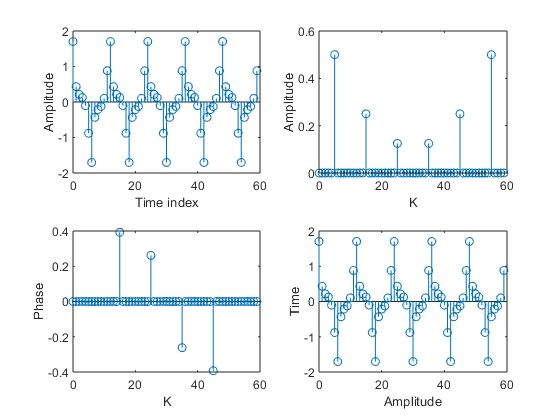

xn = g;
[Xk] = dft(g);
Xk(Xk<(1*(10^ - 10) + i*1*(10^ - 10))) = 0 + i*0;

%plot the input sequence
t=0:length(xn)-1;
figure
subplot(221);
stem(t,xn);
ylabel ('Amplitude')
xlabel ('Time index')

%plot the magnitude sequence
mag = abs(Xk);
%mag=10*log10(mag);
subplot(222);
stem(t,mag);
ylabel('Amplitude')
xlabel('K')
%plot the phase sequence
phase = angle(Xk);
subplot(223);
stem(t,phase);
ylabel('Phase')
xlabel('K')

% inverse dft
[ixk]=idft(Xk);

%plot the original 
subplot(224);
stem(t,real(ixk))
xlabel ('Amplitude')
ylabel ('Time')

# Unit testing for some of the below functions

ConsolidateFreqs test

kNuConsolidate = 0.1;
nu_MFT = [1, 5, 5.05, 6, 16, 16.025, 25, 25];
ConsolidateFreqs(nu_MFT,kNuConsolidate)

ConsolidateFreqsByBracket

kNuConsolidate = 0.1;
nu_MFT = [1, 5, 5.05, 6, 16, 16.025, 25, 25, 30, 32, 32.075, 45, 59];
bracket = [4,5,4];
ConsolidateFreqsByBracket(nu_MFT,bracket,kNuConsolidate)

Manual FFT unit test

kNuConsolidate = 0.1;
f = [1, 5, 5.05, 6, 16, 16.025, 25, 25, 30, 32, 32.075, 45, 59];
bracket = [4,5,4];
[~,~]=MFT(g,t,f,bracket);

nu_MFT =     1.0000    5.0250    6.0000   16.0125   25.0000   30.0000   32.0375   45.0000   59.0000


# Functions

## DFT

## 
$$X_k = \frac{1}{N}\sum_{n=0}^{N-1}X_ne^{-i2\pi kn/N}$$


Note:  I like to put the 1/N in the forward DFT since it gives the actual values of the time spikes.  It can go on either side.

function [Xk] = dft(xn)
N = length(xn);         % Length of the input
Xk=zeros(1,N);          % initialize the output
i=sqrt(-1);
for k=0:N-1
    for n=0:N-1
        Xk(k+1)=(Xk(k+1)+(xn(n+1)*exp((-i)*2*pi*k*n/N)));
    end
end
 Xk = Xk./N;
end

## Inverse DFT

## 
$$x_n = \sum_{n=0}^{N-1}X_ke^{i2\pi kn/N}$$


function [ixk] = idft(Xk)
N = length(Xk);
ixk = zeros(1,N);
i = sqrt(-1);
for n=0:N-1
    for k = 0:N-1
        ixk(n+1) = ixk(n+1)+(Xk(k+1)*exp(i*2*pi*k*n/N));
    end
end
end

# Manual FFT (MFT)

function [freqs, MFT] = MFT_Live(g, t, f, bracket)
%
% Ported from VBA by Allen Goldstein, NIST from:
% http://jonova.s3.amazonaws.com/cfa/climate.xlsm
% written by: Dr David Evans
%             david.evans@sciencespeak.com
%
%===============================================================================================
%
% * Manual Fourier Transform for equally spaced time series.
% * "Manual" means that the exact Cosine/Sine frequencies to be calculated 
%     are pre-assumed before the MFT is called.
% * This is different from a DFT or FFT in that the frequencies of those 
%     are fixed based on the Extent and the sampling rate of the time series.
%
% * This code moves frequencies moves frequencies outside the Nyquist limit 
%    to inside the range (caution), removes frequecies that are very close to each other, 
%    and orders frequencies by amplitude.
%
% * Input:
%       g   [0..N-1]    Time series
%       t   [0..N-1]    Time of the data points (must be regular (equally spaced))
%       f   [1..nFreqs] Frequncies at which the MFT will assume their are frequencies
%       bracket [1..nBrackets] Number of frequencies per bracket.  If < 0, use only one bracket
%
% * Output:
%       freqs [1..nFreqs]   Frequencies with significant sinusoidsafter consolidation of close frequencies.
%                           note that this may be smaller than input "f[0..nFreqs]
%       MFT [1..nFreqs]     Complex MFT

%-------------------------------------------------------------------------------------------------------
kNuConsolidate = 0.1;   % How close should frequencies be allowed to get before they are consolidated
% Setting the consolidation distance:
%
%- Smaller naturally leads to greater discriminination between frequencies. Down to 0.002 tested ok.
%- Larger causes more consolidation of neighbouring frequencies, possibly gets waylaid in very local
%  maxima caused by two frequencies converging on same actual frequency. Seems to bve connected with number of iterations
%  allowed in MinimizeResidualByVaryingMultipleFreqs. Anyway, larger makes it better at finding frequencies
%  in synthesized time series. Tested up to 0.25 well.
%- Presuumably should set this based on how far apart sinusoids are expected in the time seires under analysis.
%- 0.08 seems like a good comporomise for the synthetics here.
%-------------------------------------------------------------------------------------------------------

t0 = t(1);              % first time in the series
Fs = 1/mean(diff(t));   % time series sample rate
E = t(end)-t0 + 1/Fs;   % Extent (the length of the series plus one/half sample period before and after)

nu_MFT = f;


% The Optimal Fourier Transform process may send the MFT some freqs that are converging.  
% We need to identify and consolidate those freqs
if any(bracket) < 0
    [nu_MFT] = ConsolidateFreqs(nu_MFT,kNuConsolidate);
else
    [nu_MFT] = ConsolidateFreqsByBracket (nu_MFT, bracket,kNuConsolidate)
end

kMaxNSAtOnce = length(nu_MFT);
nuV = zeros(1,kMaxNSAtOnce);
nFreqsDone = 0;
bracketIx = 0;
nLeftThisBracket = 0;
while nFreqsDone < length(nu_MFT)
  
    nNuV = kMaxNSAtOnce;
    if ~isempty(bracket)        % Do all bracketing here
        if nLeftThisBracket == 0
            bracketIx = bracketIx + 1;
            if bracketIx <= length(bracket)
                nLeftThisBracket = bracket(bracketIx);
            else
                nLeftThisBracket = 99999;
            end
            if nNuV > nLeftThisBracket
                nNuV = nLeftThisBracket;
                nLeftThisBracket = 0;
            else
                nLeftThisBracket = nLeftThisBracket - nNuV;
            end
        end
    end
    for i=1:nNuV
        nuV(i) = nu_MFT(nFreqsDone + i);
    end
    
    [MFT] = EstimateContainedSinusoids (g,t,nuV)
    
    if nFreqsDone + nNuV < length(nu_MFT)
        %SubractMultipleSinusoidsFromTS()
    end
    
    for i = 1:nNuV
        nFreqsDone = nFreqsDone + 1;
        freqs(nFreqsDone) = nuV(i) / E;
    end
   
end



end

## MFT Helper functions

## ConsolidateFreqs

function [nu_MFT] = ConsolidateFreqs(nu_MFT,kNuConsolidate)
% Consolidates converging frequencies (those with indices very close together)
nu = nu_MFT;
nRemoved = 0;
nFreqs = length(nu);

for i = 1:nFreqs 
    if nu(i) >= 0
        for j = i+1:nFreqs
            if abs(nu(i)-nu(j)) < kNuConsolidate
                nu(i) = (nu(i) + nu(j)) * 0.5;
                nu(j) = -1;
                nRemoved = nRemoved +1;
            end
        end
    end
end

if nRemoved > 0
    j = 0;
    for i = 1:nFreqs-nRemoved
        j = j+1;
        if nu(j) >= 0
            if i ~= j
                nu(i) = nu(j);
            end
        else
            while nu(j) < 0
                j = j+1;
                if j > nFreqs
                    break
                end
                nu(i) = nu(j);
            end
        end
    end
    nFreqs = nFreqs - nRemoved;
end

nu_MFT = nu(1:nFreqs);
end

## ConsolidateFreqsByBracket

function [nu_MFT] = ConsolidateFreqsByBracket(nu_MFT, Bracket, kNuConsolidate)
% Consolidates converging frequencies but only within the same bracket

nu = nu_MFT;
nBrackets = length(Bracket);
readBase = 0;
writeBase = 0;
Consolidated = false;

for bracketIx = 1:nBrackets
    nTemp = Bracket(bracketIx);
    temp = zeros(1:nTemp);
    
    for i = 1:nTemp
        temp(i) = nu(readBase + i);     % Copy the freqs in the bracket to temp
    end
    readBase = readBase + nTemp;
    
    [temp] = ConsolidateFreqs(temp,kNuConsolidate);
    if length(temp)<nTemp
        for i = 1:length(temp)
            nu(writeBase+i) = temp(i);
        end
        Consolidated = true;
    else
        if Consolidated
            for i = 1:length(temp)
                nu(writeBase+i)=temp(i);
            end
        end
    end
    writeBase=writeBase+length(temp);   
end
nu_MFT = nu(1:writeBase);
end

## EstimateContainedSinusoids

function [MFT] = EstimateContainedSinusoids(g,t,nu)
% estimates sinusoids listed in nu()
% Ported (with some changes listed below) from VBA by Allen Goldstein, NIST from:
% http://jonova.s3.amazonaws.com/cfa/climate.xlsm
% written by: Dr David Evans
%             david.evans@sciencespeak.com
%
% changes:  
%   - This code wors only with "regular" time serise data "g".  Regular means that the sampling rate of the data is constant.
%   - Rather than returning separate sine and cosine parts, this returns complex "MFT" values
%===============================================================================================%
% - input:
%       g [0..N-1] Time Series Data
%       t [0..N-1] time of the data points
%       nu [1..M]  distinct, real-valued frequency indices.  Algorithm fails if the nu values are extremely close together so consolidate first.
% - output:
%       MFT [1..M] complex sine and cosine parts
%

[isEdgeNu] = ClassifyRegFreqsAsEdgeOrNormal(length(g),nu)
[aa] = ComputeTheAAMatrix(length(g),nu);

[]

end

## ClassifyRegFreqsAsEdgeOrNormal

function [isEdgeNu] = ClassifyRegFreqsAsEdgeOrNormal(n,nu)
% 
%-----------------------------------------------------------------------------------------------
kNuEgdeWidth = 0.00005
% 'Choosing the edgewidth
%----------------------
%- As a nu approaches an edge (0 or N/2):
%   1. The sine average at that nu approaches zero.
%   2. The row of the "aa" matrix for the sine average in that nu approaches all zeroes.
%   3. The col of the "aa" matrix for the sine part for that nu approaches all zeroes.
%- In this case, can get absurdly high values of the sine part at that freq, as it makes little difference to
%  anything in the equations described by aa. The amplitudes of the sinusoids thus found appear to "blow up",
%  becoming absurdly high.
%- The equations are correct, but it seems the suprod values that populate aa are wrong -- simply
%  because they are very small (typically E-10 and E-20) and thus dominated by roundoff error. So the values in
%  the aa matrix become random, so the computed values of the sine part at this nu becomes absurdly wrong.
%- The solution is to declare the zone close to the edge "the edge zone", where the edge zone covers all
%  the nu's where the roundoff error in suprod values is significant. In the edge zone, simply treat the
%  nu as at the edge, and thus omit the equation from the "aa" matrix.
%- Set the edge zone by trial and error, guided by assorted_TestEstimatingMultipleContainedSinusoids.
%  Obvously want the edge width to be as small as possible to get more accurate results, but big enough
%  to avoid the effect of roundoff in computing suprod values.
%- The value of aa that is the smallest, and thus most vulnerable to suprod roundoff, is at the
%  intersection of the row for the sine average of nu and the col for the sine part for nu, the ss suprod
%  value. At the nu near the edge, cc ~ 1, cs = sc ~ 10^-d, ss ~ 10^-2d. The roundoff error of a suprod
%  value using double arithemtic (which is good for 15 decimal places) for time series of 1000 data points or so
%  creates a noise floor around 10^-12 or so. So d is about 6, i.e. set edgewidth so ss(edgewidth) is around
%  10^-12.
%- Set the tol in TestEstContainedSinusoidOnce very low (maybe 10^-7) then watch the failure messages
%  for the degenerate cases as adjust kNuEdgeWidth. To stop the misses blowing up, need kNuEdgeWidth >= 10^-6,
%  or 10^-5 to be surer. Make it too large however, and get other errors ramping up due to artificial movement of
%  frequencies to the edge. Best compromise seems to be about 0.00002.
%- Note that the nu values for EstimateContainedSinusoids must be sufficiently distinct that the rows and
%  cols of aa are not close to being linearly dependent. So consolidate the frequencies first.
%-----------------------------------------------------------------------------------------------

halfNMinus = (n/2) - kNuEgdeWidth;
halfNPlus = (n/2) + kNuEgdeWidth;
isEdgeNu = false(1,length(nu));
for i = 1:length(nu)
    nuVal=nu(i);
    if nuVal <= kNuEgdeWidth
        if nuVal >= -kNuEgdeWidth
            isEdgeNu(i)=true;
        else
            [nuVal] = MoveFreqIxInto0ToHalfN(n,nuVal);
            isEdgeNu(i)= (nuVal < kEdgeWidth) | (nuVal > halfNMinus);
        end
    else
        if nuVal >= halfNMinus
            if nuVal <= halfNPlus
                isEdgeNu(i)= true;
            else
                [nuVal] = MoveFreqIxInto0ToHalfN(n,nuVal);
                isEdgeNu(i)= (nuVal < kEdgeWidth) | (nuVal > halfNMinus);
            end
        end
    else
        isEdgeNu(i)=false
    end
end

end

## ComputeTheAAMatrix

function [aa]=ComputeTheAAMatrix(n,nu,isEdgeNu)
Private Sub ComputeTheAAMatrix(ByVal n&, regular As Boolean, normTime() As Double, nu() As Double, ByVal nNu)
%- Computes aa array.
%- Degenerate case of a zero row in the "aa" matrix arises iff row is for sine part of an edge nu (0 or N/2).
%- "aa" is a square symmetric matrix: 2 rows and cols for each normal nu, one row and col for each edge nu.

rowN = 1;
for i=1:length(nu)
    colN = 1;
    if isEdgeNu(i)          % row for edge nu
        for j = 1:i         % col
            [cc,cs,sc,ss] = CalcRegSuprods (nu(i), nu(j), n);
            if isEdgeNu(j)
                aa(rowN,colN)=cc;
                if j < i
                    aa(colN, rowN)=cc;
                end
                colN = colN+1;
            else
                aa(rowN,colN)=cc;
                aa(rowN,colN+1)=cs;
                if j < i
                    aa(colN,rowN)=cc;
                    aa(coln+1,rowN)=cs;
                end
                colN = colN+1;
            end
        end
        rowN = rowN+1;
    else
        for j = 1:i
            [cc,cs,sc,ss] = CalcRegSuprods (nu(i), nu(j), n);
            if isEdgeNu(j)
                aa(rowN,colN) = cc;
                aa(rowN+1,colN) = sc;
                if j < i 
                    aa(colN,rowN) = cc;
                    aa(colN,rowN+1) = sc;
                end
                colN = colN+1;
            else
                aa(rowN,colN)=cc;
                aa(rowN,colN+1)=cs;
                aa(rowN+1,colN)=sc;
                aa(rowN+1,colN+1)=ss;
                if j < i
                    aa(colN,rowN)=cc;
                    aa(colN+1,rowN)=cs;
                    aa(colN,rowN+1)=sc;
                    aa(colN+1,rowN+1)=ss
                end 
            end 
            colN=colN+2;
        end
        rowN = rowN+2
    end
end
    [r,R]=FlagLowElementsInMatrix(aa,length(nu))
end

Illegal use of reserved keyword "else".